clc
close all; 
clear;

This script is used to analyze the impact of time step on the calculated RMS power 

## Power Profile Analysis

### Load power profiles 

Get the directory of the power profiles from H24

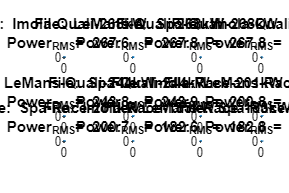

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

timeStep = 0.1000

% InputPar.PowerProfile.Folder= "\\wae-fs01\Department\WAE\Business Development\!Proposals\M1444B1 - Mission H24\Technical\240610_Drive Cycle";
InputPar.PowerProfile.Folder="InputDriveCycleProfiles";
InputPar.PowerProfile.Name = "P006-1040-019-A-------Battery_Load_WAE.xlsx";
InputPar.PowerProfile.Dir= fullfile(InputPar.PowerProfile.Folder,InputPar.PowerProfile.Name );

sheetName = sheetnames(InputPar.PowerProfile.Dir);
% read the table for each sheet
fig1= figure('Color','White','Position',[680,7,1500,1000]);
for isheet = 1: length(sheetName)
    data= readtable(InputPar.PowerProfile.Dir,Sheet=sheetName(isheet));
    data.Properties.VariableNames=["sRun_m","Time_Seconds","vCar_kph","Power_kW","Power_RMS_kW"];

    data.Power_kW = -data.Power_kW;
    PowerProfile.(sheetName(isheet))= data;
    
    nexttile()
    plot(data.Time_Seconds, data.Power_kW);
    grid on 
    xlabel('Time (s)'); ylabel('Power (kW)');

    
    %
   InputPowerProfileTotal= data(:,[2,4]);
   timeStep=0.1;
   [TimeEnd, dTime,PowerInput]=MissionHelper.InputProfileProcessingNewName(InputPowerProfileTotal,timeStep);
    
    RMS_interp= rms(PowerInput.Data);

    titleName= strrep(sheetName(isheet), "_","-");
    title(sprintf("File: %s \n Power_{RMS}= %.1f", titleName, RMS_interp));
    
end

f=figure('Color','White','Position',[680,7,1200,600]);
set(f, 'Visible', 'on');
tiledlayout(1,2)
ax1=nexttile

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1111 0.1100 0.3414 0.8150]
            Units: 'normalized'

  Show all properties


plot(diff(data.Time_Seconds))
title('dTime');
xlabel('Sample points');
ylabel('dT (s)');
grid on

ax2=nexttile

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5636 0.1100 0.3414 0.8150]
            Units: 'normalized'

  Show all properties


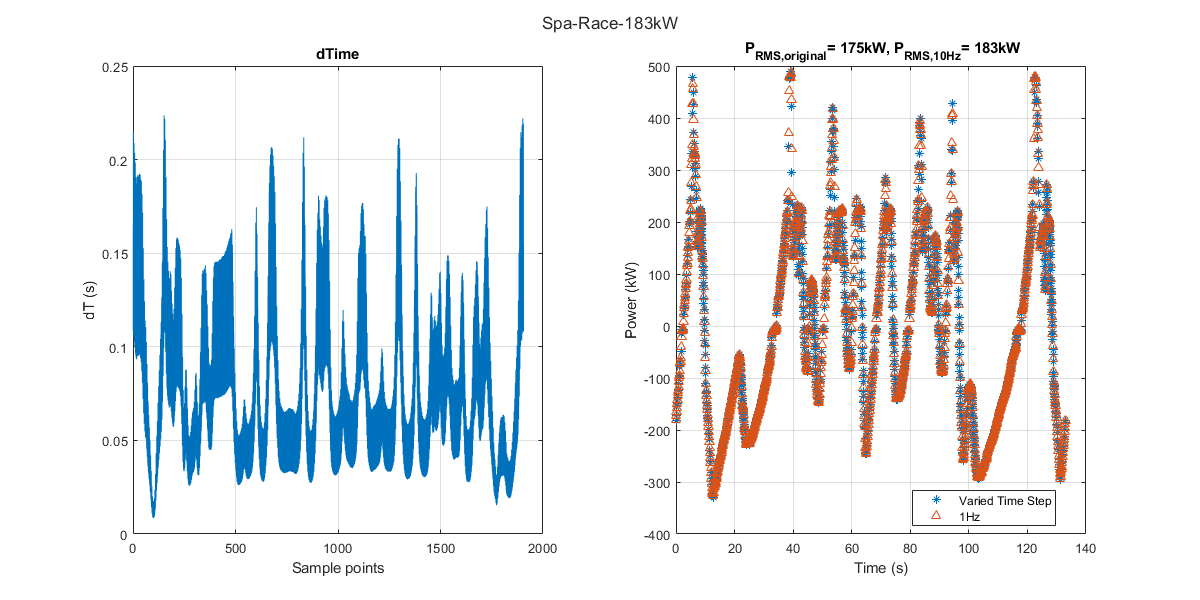

plot(data.Time_Seconds,data.Power_kW,'*','DisplayName','Varied Time Step')
hold on 
plot(PowerInput,'^','DisplayName','1Hz')
grid on
% Compute RMS values
rms_original = rms(data.Power_kW);
rms_10Hz = rms(PowerInput.Data);

title_string = sprintf(' P_{RMS,original}= %.0fkW, P_{RMS,10Hz}= %.0fkW', ...
                    rms_original, rms_10Hz);
title(title_string);

% linkaxes([ax1, ax2])
xlabel('Time (s)');
ylabel('Power (kW)');
grid on
legend(Location='best')
sgtitle(titleName)